# Lidar and Camera Calibration

This example shows you how to estimate the rigid transformation between a 3-D lidar and a camera. At the end of this example, you will be able to use the rigid transformation matrix to fuse lidar and camera data.

This diagram explains the workflow for the lidar and camera calibration (LCC) process.

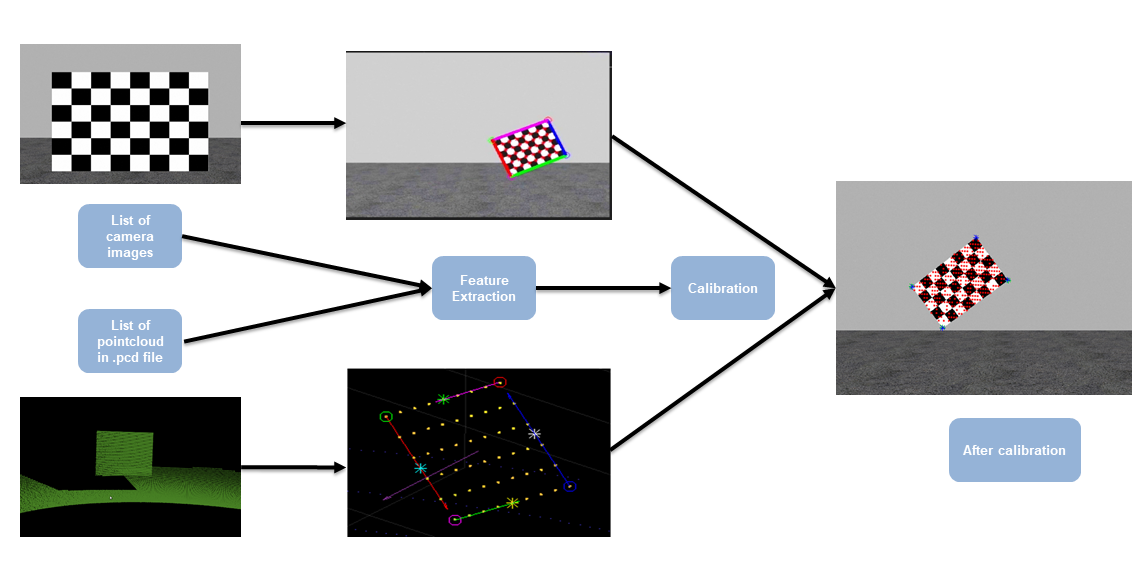

## Overview

Lidar and camera sensors are the most common vision sensors in autonomous driving applications. Cameras provide rich color information and other features that can be used to extract different characteristics of the detected objects. Lidar sensors, on the other hand, provide an accurate 3-D location and structure of the objects. To enhance the object detection and classification pipeline, data from these two sensors can be fused together to get more detailed and accurate information on the objects.

The transformation matrix in the form of orientation and relative positions between the two sensors is the precursor to fusing data from these two sensors. Lidar camera calibration helps in estimating the transformation matrix between 3-D lidar and a camera mounted on the autonomous vehicle. In this example, you will use data from two different lidar sensors, `HDL64` and `VLP16`. `HDL64` data is collected from a Gazebo environment as shown in this figure.

                        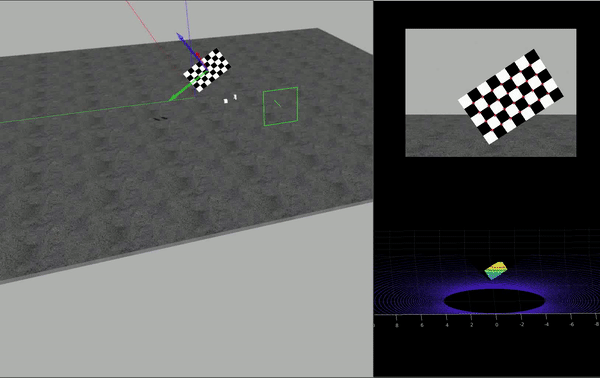

Data is captured in the form of set of PNG images and corresponding PCD point clouds. This example assumes that the camera's intrinsic parameters are known. For more information on extracting a camera's intrinsic parameters, see Single Camera Calibration. 

## Load Data

Load Velodyne HDL-64 sensor data from Gazebo.

imagePath = fullfile(toolboxdir('lidar'), 'lidardata', 'lcc', 'HDL64', 'images');
ptCloudPath = fullfile(toolboxdir('lidar'), 'lidardata', 'lcc', 'HDL64', 'pointCloud');
cameraParamsPath = fullfile(imagePath, 'calibration.mat');

intrinsic = load(cameraParamsPath); % Load camera intrinsics
imds = imageDatastore(imagePath); % Load images using imageDatastore
pcds = fileDatastore(ptCloudPath, 'ReadFcn', @pcread); % Load point cloud files

imageFileNames = imds.Files;
ptCloudFileNames = pcds.Files;

squareSize = 200; % Square size of the checkerboard

% Set random seed to generate reproducible results.
rng('default'); 

## Checkerboard Corner Detection

This example uses a checkerboard pattern as the feature of comparison. Checkerboard edges are estimated using lidar and camera sensors. Use `estimateCheckerboardCorners3d `to calculate coordinates of the checkerboard corners and size of actual checkerboard in *mm*. The corners are estimated in 3-D with respect to the camera's coordinate system. For more details on camera coordinate systems, see[ Coordinate Systems in Lidar Toolbox.](docid:lidar_ug#mw_353a3bc0-24a8-4025-ac67-92db32888d47)

[imageCorners3d, checkerboardDimension, dataUsed] = ...
    estimateCheckerboardCorners3d(imageFileNames, intrinsic.cameraParams, squareSize);
imageFileNames = imageFileNames(dataUsed); % Remove image files that are not used

The results can be visualized using the helper function `helperShowImageCorners`.

% Display Checkerboard corners
helperShowImageCorners(imageCorners3d, imageFileNames, intrinsic.cameraParams);

## Checkerboard Detection in Lidar

Similarly, use `detectRectangularPlanePoints` function to detect a checkerboard in the lidar data. The function detects rectangular objects in the point cloud based on the input dimensions. In this case, it detects the checkerboard using the board dimensions calculated in the previous section.

% Extract ROI from the detected image corners
roi = helperComputeROI(imageCorners3d, 5);

% Filter point cloud files corresponding to the detected images
ptCloudFileNames = ptCloudFileNames(dataUsed);
[lidarCheckerboardPlanes, framesUsed, indices] = ...
    detectRectangularPlanePoints(ptCloudFileNames, checkerboardDimension, 'ROI', roi);

% Remove ptCloud files that are not used
ptCloudFileNames = ptCloudFileNames(framesUsed);
% Remove image files 
imageFileNames = imageFileNames(framesUsed);
% Remove 3D corners from images
imageCorners3d = imageCorners3d(:, :, framesUsed);

To visualize the detected checkerboard, use `helperShowLidarCorners` function.

helperShowLidarCorners(ptCloudFileNames, indices);

## Calibrating Lidar and Camera

Use `estimateLidarCameraTransform to` estimate the rigid transformation matrix between lidar and camera. 

[tform, errors] = estimateLidarCameraTransform(lidarCheckerboardPlanes, ...
    imageCorners3d, 'CameraIntrinsic', intrinsic.cameraParams);

After calibration is completed, you can use calibration matrix in two ways:

- Project Lidar point cloud on image.

- Enhance Lidar point cloud using color infromation from image.

Use `helperFuseLidarCamera` `function` to visualize the lidar and the image data fused together.

helperFuseLidarCamera(imageFileNames, ptCloudFileNames, indices, ...
    intrinsic.cameraParams, tform);

## Error Visualization

Three types of errors are defined to estimate the accuracy of the calibration:

- Translation Error: Mean of difference between centroid of checkerboard corners in the lidar and the projected corners in 3-D from an image.

- Rotation Error: Mean of difference between the normals of checkerboard in the point cloud and the projected corners in 3-D from an image.

- Reprojection Error: Mean of difference between the centroid of image corners and projected lidar corners on the image.

Plot the estimated error values by using helperShowError.

helperShowError(errors)

## Results

After calibration check for data with high calibration errors and re-run the calibration.

outlierIdx = errors.RotationError < mean(errors.RotationError);
[newTform, newErrors] = estimateLidarCameraTransform(lidarCheckerboardPlanes(outlierIdx), ...
        imageCorners3d(:, :, outlierIdx), 'CameraIntrinsic', intrinsic.cameraParams);
    helperShowError(newErrors);


## Testing on Real Data

Test the LCC workflow on actual VLP-16 Lidar data to evaluate its performance.

clear;
imagePath = fullfile(toolboxdir('lidar'), 'lidardata', 'lcc', 'vlp16', 'images');
ptCloudPath = fullfile(toolboxdir('lidar'), 'lidardata', 'lcc', 'vlp16', 'pointCloud');
cameraParamsPath = fullfile(imagePath, 'calibration.mat');

intrinsic = load(cameraParamsPath); % Load camera intrinscs
imds = imageDatastore(imagePath); % Load images using imageDatastore
pcds = fileDatastore(ptCloudPath, 'ReadFcn', @pcread); % Loadr point cloud files

imageFileNames = imds.Files;
ptCloudFileNames = pcds.Files;

squareSize = 81; % Square size of the checkerboard

% Set random seed to generate reproducible results.
rng('default');

% Extract Checkerboard corners from the images
[imageCorners3d, checkerboardDimension, dataUsed] = ...
    estimateCheckerboardCorners3d(imageFileNames, intrinsic.cameraParams, squareSize);

imageFileNames = imageFileNames(dataUsed); % Remove image files that are not used

% Filter point cloud files corresponding to the detected images
ptCloudFileNames = ptCloudFileNames(dataUsed);

% Extract ROI from the detected image corners
roi = helperComputeROI(imageCorners3d, 5);

%Extract Checkerboard in lidar data
[lidarCheckerboardPlanes, framesUsed, indices] = detectRectangularPlanePoints(...
    ptCloudFileNames, checkerboardDimension, 'RemoveGround', true, 'ROI', roi);
imageCorners3d = imageCorners3d(:, :, framesUsed);
% Remove ptCloud files that are not used
ptCloudFileNames = ptCloudFileNames(framesUsed);
% Remove image files 
imageFileNames = imageFileNames(framesUsed);
[tform, errors] = estimateLidarCameraTransform(lidarCheckerboardPlanes, ...
    imageCorners3d, 'CameraIntrinsic', intrinsic.cameraParams);
helperFuseLidarCamera(imageFileNames, ptCloudFileNames, indices,...
    intrinsic.cameraParams, tform);
% Plot the estimated error values
helperShowError(errors);

## Summary

This example gives an overview on how to get started with the lidar camera calibration workflow, to extract a rigid transformation between the two sensors. This example also shows you how to use the rigid transformation matrix to fuse lidar and camera data.

## References

[1] Lipu Zhou and Zimo Li and Michael Kaess, "Automatic Extrinsic Calibration of a Camera and a 3D LiDAR using Line and Plane Correspondences", "IEEE/RSJ Intl. Conf. on Intelligent Robots and Systems, IROS", Oct, 2018.

[2] K. S. Arun, T. S. Huang, and S. D. Blostein, “Least-squares fitting of two 3-D point sets,” IEEE Transactions on Pattern Analysis and Machine Intelligence, vol. PAMI-9, no. 5, pp. 698–700, Sept 1987.

*Copyright 2019 The MathWorks, Inc.*